# b) External Controls, Adds controls in hydraulic analysis STEP-BY-STEP.

### This example contains: 

- Load network. 

- Delete Controls. 

- Hydraulic analysis STEP-BY-STEP. 

- CONTROLS:  Add new controls in live. 

- Delete controls. 

- Unload library.

### Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


### Second way

### Load network.

d = epanet('Net1.inp');

EPANET version {20200} loaded (EMT version {v2.2.1}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded sucessfuly.


### Delete Controls.

d.deleteControls();
tankID = '2';
pumpID = '9';

tankIndex = d.getNodeIndex(tankID);
pumpIndex = d.getLinkIndex(pumpID);
tankElevation = d.getNodeElevations(tankIndex);

### Hydraulic analysis STEP-BY-STEP.

d.openHydraulicAnalysis;
d.initializeHydraulicAnalysis(0);

tstep = 1;
T = []; P = []; F = []; S= [];i=1;


### CONTROLS

while (tstep>0)
    
    H = d.getNodeHydaulicHead;
    tankHead(i) = H(tankIndex)-tankElevation;
    i = i+1;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Add new controls in live.
    Below = 110;
    Above = 140;
    status = {'OPEN', 'CLOSED'};

    % LINK 9 OPEN IF NODE 2 BELOW 110
    d.addControls(['LINK ', pumpID, ' ', status{1}, ' IF NODE ', tankID,...
        ' BELOW ', num2str(Below)]);
    
    % LINK 9 CLOSED IF NODE 2 ABOVE 140
    d.addControls(['LINK ', pumpID, ' ', status{2}, ' IF NODE ', tankID,...
        ' ABOVE ', num2str(Above)]);
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    t = d.runHydraulicAnalysis;
    
    S = [S; d.getLinkStatus(pumpIndex)];
    F = [F; d.getLinkFlows];
    P = [P; d.getNodePressure(1)];
    T = [T; t];
    
    tstep = d.nextHydraulicAnalysisStep;
    
    % Delete controls.
    d.deleteControls();
end
d.closeHydraulicAnalysis;

### Unload library.

d.unload;

EPANET Class is unloaded


### Create Figures

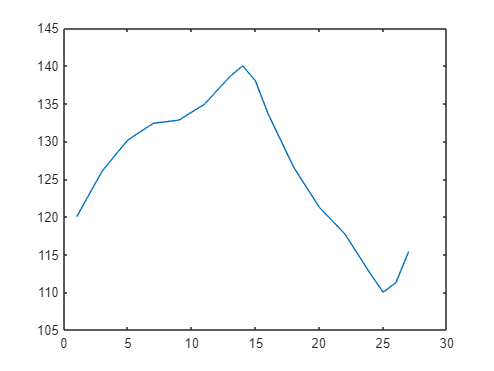

figure;
plot(tankHead)

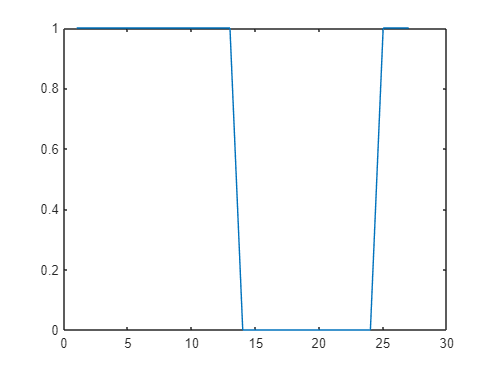

figure;
plot(S)